load('data\\shimizu_25kg.mat');
load('data\\shimizu_5kg.mat');
load('data\\shimizu_75kg.mat');
load('data\\shimizu_10kg.mat');
load('data\\shimizu_MVC100.mat');
load('data\\shimizu_5kg_reversed.mat');
load('data\\shimizu_udetate_slow.mat');
load('data\\shimizu_udetate_fast.mat');
load('data\\maruyama_25kg.mat');
load('data\\maruyama_5kg.mat');
load('data\\maruyama_75kg.mat');
load('data\\maruyama_10kg.mat');
load('data\\maruyama_MVC100.mat');
load('data\\maruyama_udetate_slow.mat');
load('data\\maruyama_udetate_fast.mat');
time=shimizu_25kg.Time;

s_weight=[shimizu_25kg; shimizu_5kg; shimizu_75kg; shimizu_10kg];
s_mvc=shimizu_MVC100;
s_ude=[shimizu_udetate_slow; shimizu_udetate_fast];


function ret=plot_and_get(raw, rmsfreq, pre, form)
    
    data=raw.Dev3_ai1;
    
    fs=1000;
    dt=1/fs;
    n=length(data);
    t=raw.Time;
    
    for i = 1:9
        d = designfilt('bandstopiir','FilterOrder',2, ...
                   'HalfPowerFrequency1',50*i-1,'HalfPowerFrequency2',50*i+1, ...
                   'DesignMethod','butter','SampleRate',fs);
        data=filter(d,data);
    end
    
    bpFilt = designfilt('bandpassiir','FilterOrder',20, ...
             'HalfPowerFrequency1',5,'HalfPowerFrequency2',500, ...
             'SampleRate',fs);
    data = filter(bpFilt,data);
    
    [psdx,f1] = periodogram(data,rectwin(n),n,fs,'ConfidenceLevel',0.95);
    
    t_rms=t(1:rmsfreq:end);
    emg_rms=zeros(n/rmsfreq,1);
    mfreq_rms=zeros(n/rmsfreq,1);
    for i=1:n/rmsfreq
        emg_tmp=data((i-1)*rmsfreq+1:i*rmsfreq);
        emg_rms(i,1)=rms(emg_tmp);
        [psdx_tmp,ftmp] = periodogram(emg_tmp,rectwin(length(emg_tmp)),length(emg_tmp),fs,'ConfidenceLevel',0.95);
        mfreq_rms(i)=medfreq(psdx_tmp,fs);
    end
    mfreq=medfreq(psdx,fs)
    
    %plot(t_rms, mfreq_rms, "Color", '#4DBEEE')
    t_rms2=seconds(t(1:rmsfreq:end-(pre+form)*fs+1));
    emg_rms2=emg_rms(pre*fs/rmsfreq:end-form*fs/rmsfreq);
    ret=polyfit(t_rms2,emg_rms2,1)

    plot(t_rms, emg_rms, "Color", '#4DBEEE');
    hold on
    plot(t_rms(pre*fs/rmsfreq:end-form*fs/rmsfreq), emg_rms(pre*fs/rmsfreq:end-form*fs/rmsfreq),"Color",'#D95319');
    plot(t_rms, polyval([ret(1) ret(2)-ret(1)*pre], seconds(t_rms)), "Color", "#FF0000");
    hold off
end

function ret=get_mvc(raw)
    data=raw.Dev3_ai1;
    
    fs=1000;
    dt=1/fs;
    n=length(data);
    t=raw.Time;
    
    for i = 1:9
        d = designfilt('bandstopiir','FilterOrder',2, ...
                   'HalfPowerFrequency1',50*i-1,'HalfPowerFrequency2',50*i+1, ...
                   'DesignMethod','butter','SampleRate',fs);
        data=filter(d,data);
    end
    
    bpFilt = designfilt('bandpassiir','FilterOrder',20, ...
             'HalfPowerFrequency1',5,'HalfPowerFrequency2',500, ...
             'SampleRate',fs);
    data = filter(bpFilt,data);
    
    rmsfreq=500;
    t_rms=t(1:rmsfreq:end);
    emg_rms=zeros(n/rmsfreq,1);
    mfreq_rms=zeros(n/rmsfreq,1);
    for i=1:n/rmsfreq
        emg_tmp=data((i-1)*rmsfreq+1:i*rmsfreq);
        emg_rms(i,1)=rms(emg_tmp);
        [psdx_tmp,ftmp] = periodogram(emg_tmp,rectwin(length(emg_tmp)),length(emg_tmp),fs,'ConfidenceLevel',0.95);
        mfreq_rms(i)=medfreq(psdx_tmp,fs);
    end
    
    plot(t_rms, emg_rms, "Color", '#4DBEEE')
    ret=mean(emg_rms(10*fs/rmsfreq:20*fs/rmsfreq));
end


'shimizu_mvc'

ans = 'shimizu_mvc'

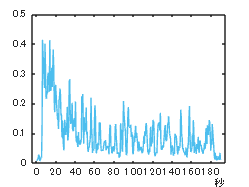

smvc = 0.2707

smvc=get_mvc(shimizu_MVC100)

'maruyama_mvc'

ans = 'maruyama_mvc'

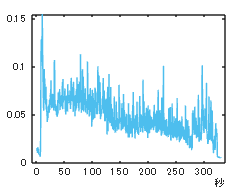

mmvc = 0.0768

mmvc=get_mvc(maruyama_MVC100)

'shimizu'

ans = 'shimizu'

mfreq = 0.6343

ret =     0.0002    0.0377


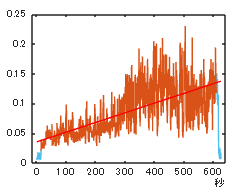

pols=zeros(4,2);
pols(1,:)=plot_and_get(shimizu_25kg,500,15,15);

mfreq = 0.7194

ret =     0.0021    0.1150


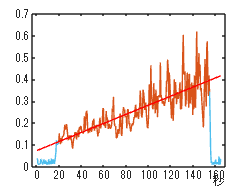

pols(2,:)=plot_and_get(shimizu_5kg,500,20,10);

mfreq = 2.1591

ret =     0.0028    0.1972


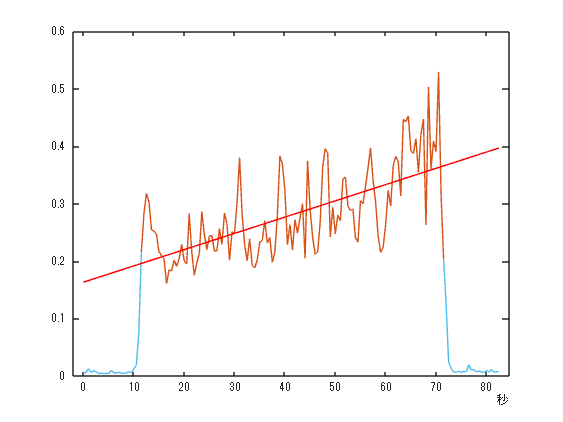

pols(3,:)=plot_and_get(shimizu_75kg,500,12,11);

mfreq = 1.0528

ret =     0.0058    0.4346


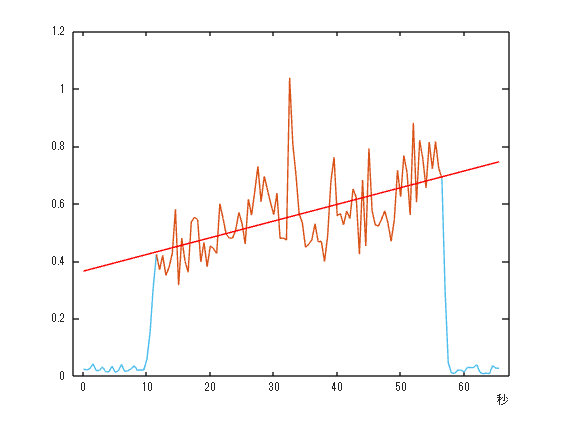

pols(4,:)=plot_and_get(shimizu_10kg,500,12,9);


pols

pols =     0.0002    0.0377
    0.0021    0.1150
    0.0028    0.1972
    0.0058    0.4346


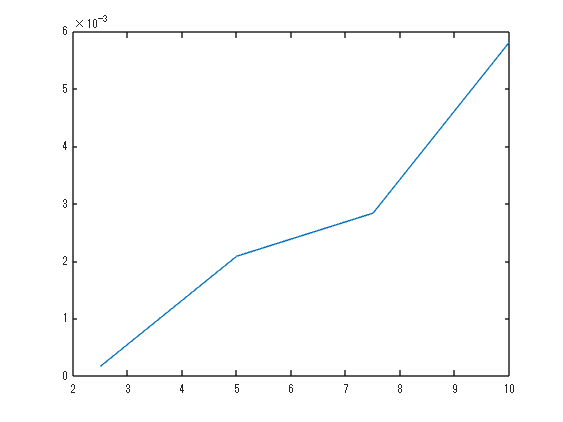

plot([2.5; 5; 7.5; 10],pols(:,1))

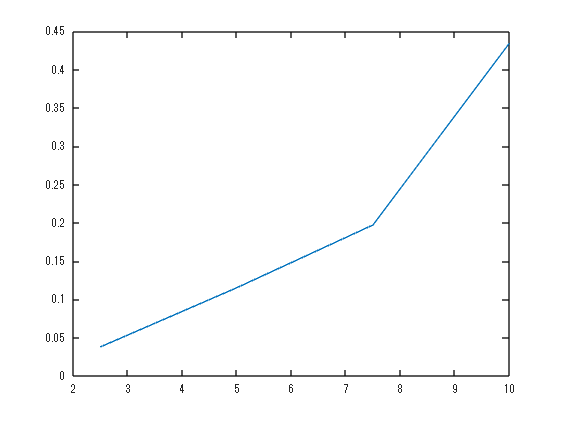

plot([2.5; 5; 7.5; 10],pols(:,2))

tire=polyfit([2.5; 5; 7.5; 10],pols(:,1),2)

tire = 1.0e-03 *

    0.0424    0.1777   -0.3764


power=polyfit([2.5; 5; 7.5; 10],pols(:,2),2)

power =     0.0064   -0.0292    0.0781


'maruyama'

ans = 'maruyama'

mfreq = 0.7093

ret =    -0.0000    0.0700


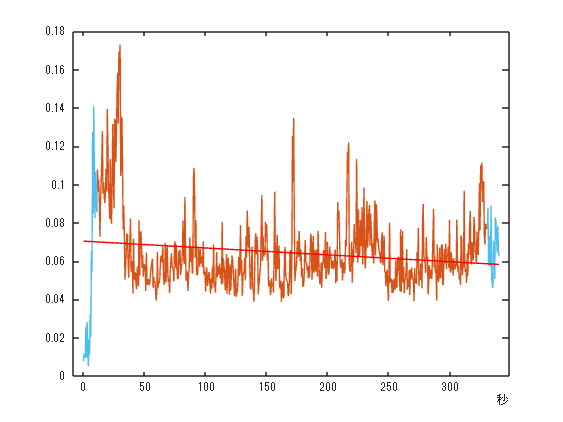

pols=zeros(4,2);
pols(1,:)=plot_and_get(maruyama_25kg,500,12,10);

mfreq = 1.4707

ret =     0.0007    0.2111


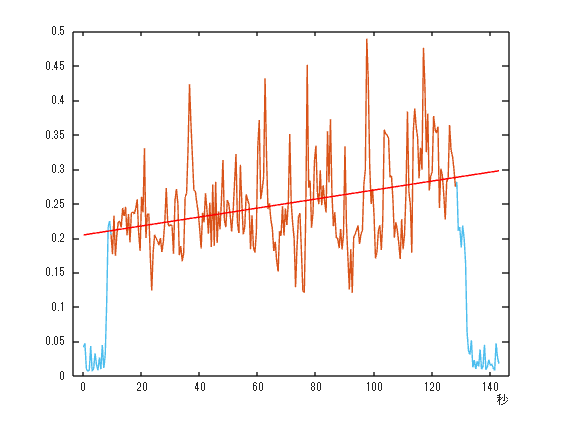

pols(2,:)=plot_and_get(maruyama_5kg,500,10,15);

mfreq = 1.4234

ret =     0.0003    0.2293


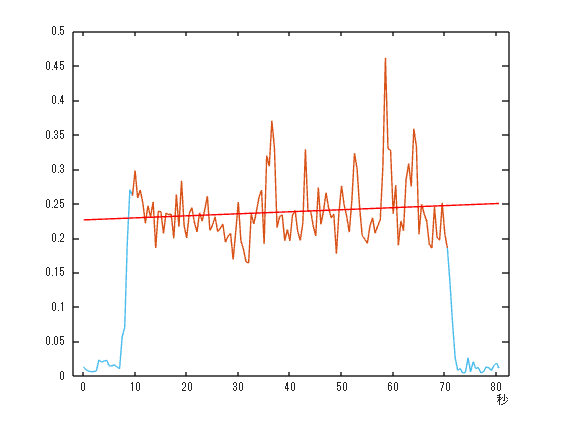

pols(3,:)=plot_and_get(maruyama_75kg,500,10,10);

mfreq = 1.5302

ret =     0.0009    0.2045


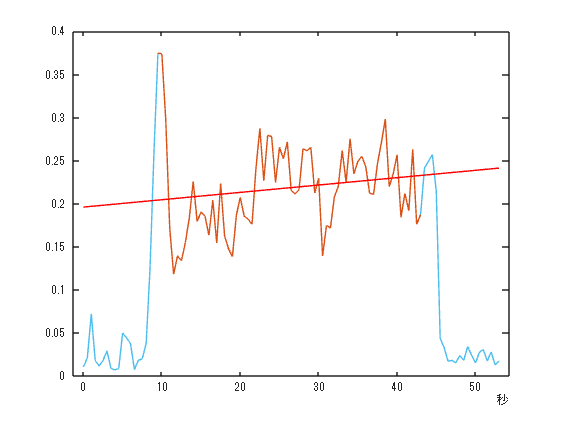

pols(4,:)=plot_and_get(maruyama_10kg,500,10,10);


pols

pols =    -0.0000    0.0700
    0.0007    0.2111
    0.0003    0.2293
    0.0009    0.2045


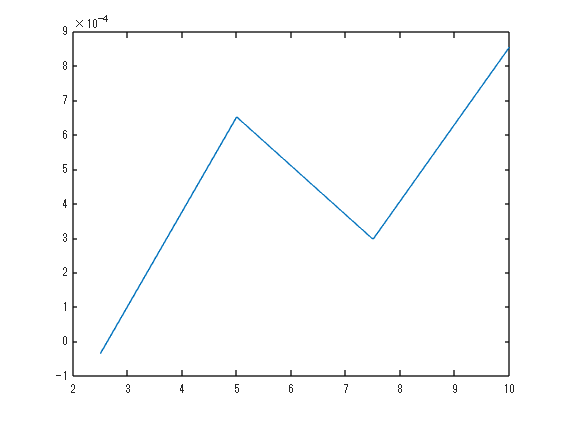

plot([2.5; 5; 7.5; 10],pols(:,1))

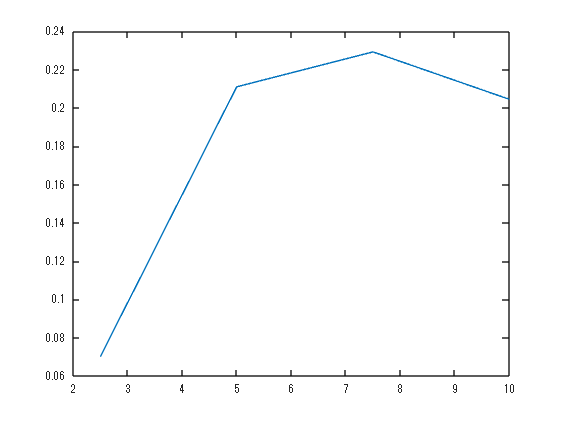

plot([2.5; 5; 7.5; 10],pols(:,2))

tire=polyfit([2.5; 5; 7.5; 10],pols(:,1),2)

tire = 1.0e-03 *

   -0.0052    0.1575   -0.2993


power=polyfit([2.5; 5; 7.5; 10],pols(:,2),2)

power =    -0.0066    0.0998   -0.1341


'reverse'

ans = 'reverse'

mfreq = 0.9417

ret =     0.0001    0.1127


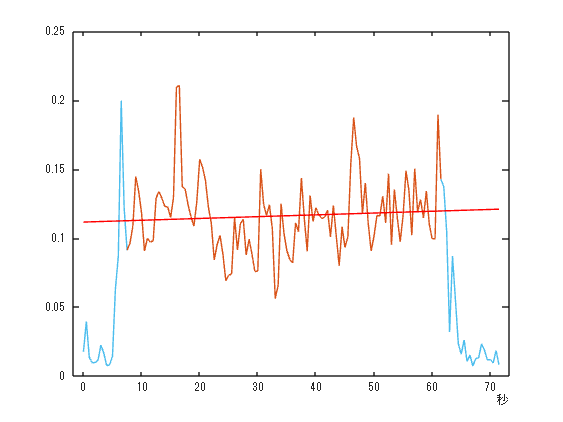

ret =     0.0001    0.1127


ret=plot_and_get(shimizu_5kg_reversed,500,8,10)

function ret=ude_analyze(raw, rmsfreq, time)
    
    data=raw.Dev3_ai1;
    
    fs=1000;
    dt=1/fs;
    n=length(data);
    t=raw.Time;
    
    for i = 1:9
        d = designfilt('bandstopiir','FilterOrder',2, ...
                   'HalfPowerFrequency1',50*i-1,'HalfPowerFrequency2',50*i+1, ...
                   'DesignMethod','butter','SampleRate',fs);
        data=filter(d,data);
    end
    
    bpFilt = designfilt('bandpassiir','FilterOrder',20, ...
             'HalfPowerFrequency1',5,'HalfPowerFrequency2',500, ...
             'SampleRate',fs);
    data = filter(bpFilt,data);
    
    [psdx,f1] = periodogram(data,rectwin(n),n,fs,'ConfidenceLevel',0.95);
    
    t_rms=seconds(t(1:rmsfreq:end));
    emg_rms=zeros(n/rmsfreq,1);
    mfreq_rms=zeros(n/rmsfreq,1);
    for i=1:n/rmsfreq
        emg_tmp=data((i-1)*rmsfreq+1:i*rmsfreq);
        emg_rms(i,1)=rms(emg_tmp);
        [psdx_tmp,ftmp] = periodogram(emg_tmp,rectwin(length(emg_tmp)),length(emg_tmp),fs,'ConfidenceLevel',0.95);
        mfreq_rms(i)=medfreq(psdx_tmp,fs);
    end
    mfreq=medfreq(psdx,fs)

    plot(t_rms, emg_rms, "Color", '#4DBEEE');
    hold on
    ret=zeros(10,1);
    for i=1:10
        plot(t_rms(time(i,1)*fs/rmsfreq:time(i,2)*fs/rmsfreq), emg_rms(time(i,1)*fs/rmsfreq:time(i,2)*fs/rmsfreq),"Color",'#D95319');
        ret(i)=rms(emg_rms(time(i,1)*fs/rmsfreq:time(i,2)*fs/rmsfreq));
    end
    hold off
end

'udetate'

ans = 'udetate'

mfreq = 8.9806

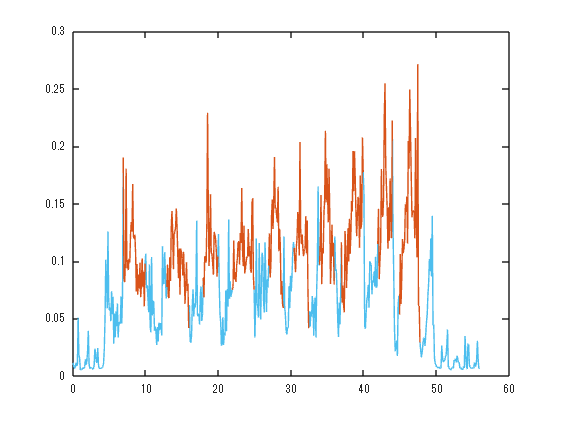

slow=ude_analyze(shimizu_udetate_slow,100,[7 10;13 16;18 20;22 25;27 29;30.5 32.5;34 36;37 40;42 44;45 47.8]);

plot(1:1:10,slow);
hold on
slow_poly=polyfit(1:10,slow,1)

slow_poly =     0.0054    0.0959


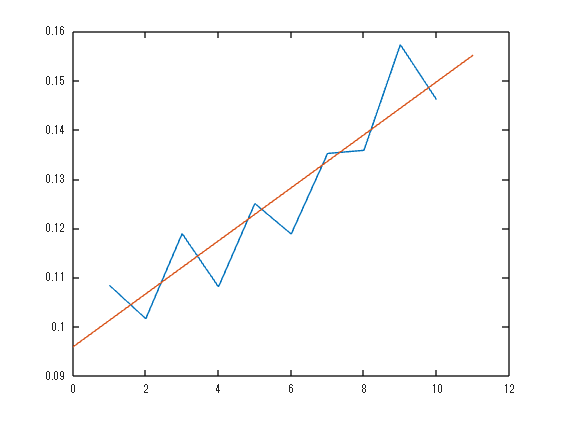

plot(0:1:11,polyval(slow_poly,0:1:11),"Color",'#D95319')
hold off

mfreq = 4.3326

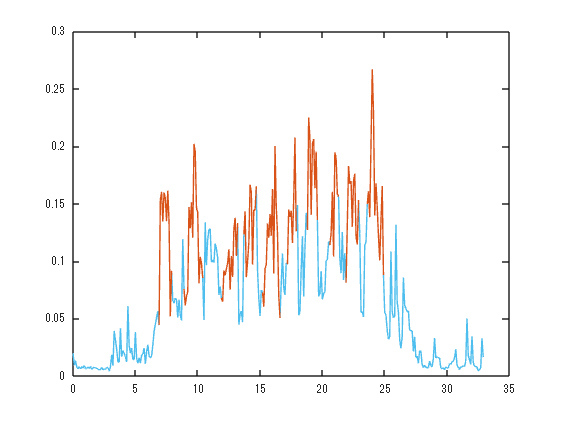

fast=ude_analyze(shimizu_udetate_fast,100,[7 8;9 10.5;12 13.3;13.8 14.8;15.3 16.7;17.3 18;18.9 19.7;20.7 21.4;22 23;23.7 25;]);

plot(1:1:10,fast);
hold on
fast_poly=polyfit(1:10,fast,1)

fast_poly =     0.0054    0.1108


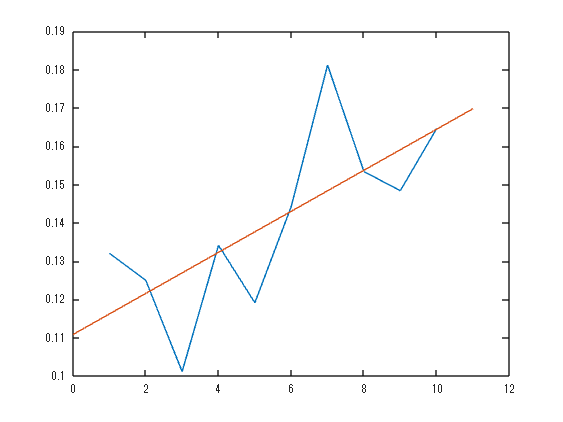

plot(0:1:11,polyval(fast_poly,0:1:11),"Color",'#D95319')
hold off